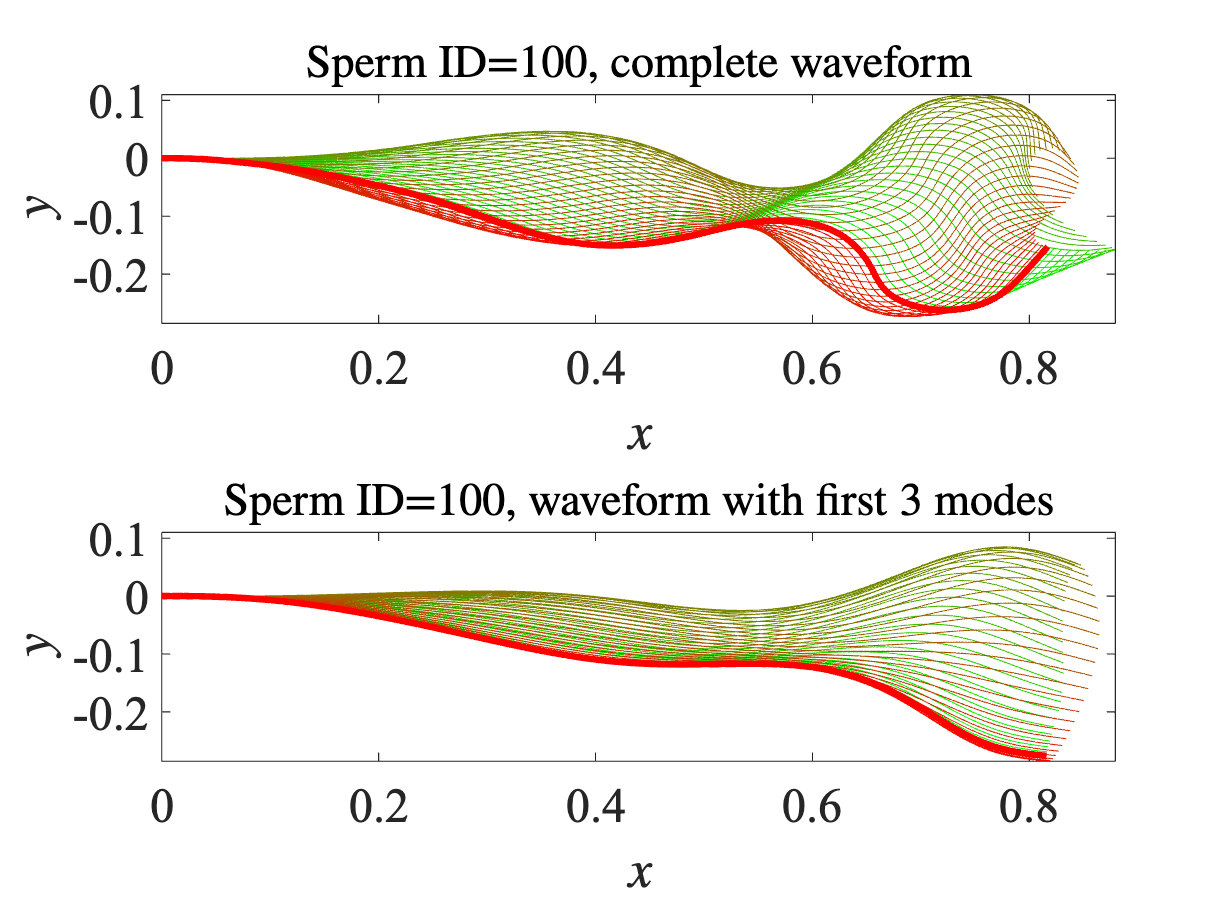

%addpath('.\Data',  '.\Functions',  '.\Images',  '.\Movies')
addpath('Data',  'Functions',  'Images',  'Movies')

clc;

if exist('coeff_op','var') && exist('modes_op','var') && exist('mu_op','var')
    clearvars -except coeff_op modes_op mu_op
else
    clear all
end

if ~exist('coeff_op', 'var')
    load('data_pca_2kModes_vShort.mat', 'coeff_op', 'modes_op', 'mu_op')
end

x_inds = 1:1000;
y_inds = 1001:2000;

sp_num = 100; % sperm cell no. whose beating you want to see; can be from 1 to 216

periods_to_run = 2; % for how many time periods do you want to visualize the beat

max_num_modes = 200; % maximum possible number of modes that can be used for reconstructing the flagellar waveform

% num_modes = randi([1 modes_max]); % user-entered number of modes to be used to reconstruct the flagellar waveform
num_modes = 3; % randi([1 modes_max]); % user-entered number of modes to be used to reconstruct the flagellar waveform

 

if periods_to_run <= 1
    periods_to_run = 2;
end

start_ind = (sp_num - 1) * 100 + 1;
end_ind   = start_ind + 99;

ind_skip = 1;

% number of colors shown in the waveform plot
nCol = numel(start_ind:ind_skip:end_ind);

% normal modes and coefficients corresponding to the three most significant
% contributions to the waveform
modes_to_use  = modes_op(:,1:num_modes);
coeffs_to_use = coeff_op(start_ind:ind_skip:end_ind,1:num_modes);

% the first 200 normal modes and coefficients (enough to accuratly represent all waveforms)
modes_max  = modes_op(:,1:max_num_modes);
coeffs_max = coeff_op(start_ind:ind_skip:end_ind,1:max_num_modes);

% setting up coloring scheme: START
startCol = [0 255 0]/255; % start color
endCol   = [255 0 0]/255; % end color

cols_r = linspace(startCol(1), endCol(1) ,nCol); % R value of RGB
cols_g = linspace(startCol(2), endCol(2) ,nCol); % G value of RGB
cols_b = linspace(startCol(3), endCol(3) ,nCol); % B value of RGB
% setting up coloring scheme: STOP

% mean x,y position of all the flagellar waveform data (all cells and at
% all times)
mu_x = mu_op(1:1000);
mu_y = mu_op(1001:2000);

% setting the xlim and ylim of the waveform-comparison movie: START
x_min = 0; x_max = 0;
y_min = 0; y_max = 0;

for i = 1:ind_skip:100

    temp = coeffs_to_use(i,:) .* modes_to_use;
    temp1 = sum(temp,2);

    temp = coeffs_max(i,:) .* modes_max;
    temp2 = sum(temp,2);

    x_min = min(x_min, min( min( temp1(x_inds) + mu_x', temp2(x_inds) + mu_x' ) ) );
    x_max = max(x_max, max( max( temp1(x_inds) + mu_x', temp2(x_inds) + mu_x' ) ) );

    y_min = min(y_min, min( min( temp1(y_inds) + mu_y', temp2(y_inds) + mu_y' ) ) );
    y_max = max(y_max, max( max( temp1(y_inds) + mu_y', temp2(y_inds) + mu_y' ) ) );

end
% setting the xlim and ylim of the waveform-comparison movie: STOP

close all

figure(1)
ax1 = subplot(2,1,1);
ax2 = subplot(2,1,2);

for pp = 1:periods_to_run

    for i = 1:ind_skip:100

        plotCol = [cols_r( (i-1)/ind_skip + 1 ), cols_g( (i-1)/ind_skip + 1 ), cols_b( (i-1)/ind_skip + 1 )];

        temp = coeffs_max(i,:) .* modes_max;
        temp_max = sum(temp,2);

        temp = coeffs_to_use(i,:) .* modes_to_use;
        temp = sum(temp,2);

        if pp == 1 % at the first time period plot waveforms to show waveform-envelope
            if mod(i,2) == 0 % plot every second waveform to make it less cluttered
                figure(1)
                ax1 = subplot(2,1,1);
                h11 = plot( temp_max(x_inds) + mu_x', temp_max(y_inds) + mu_y', 'color', plotCol); hold all
                
                ax2 = subplot(2,1,2);
                h12 = plot( temp(x_inds) + mu_x', temp(y_inds) + mu_y', 'color', plotCol); hold all
            end
        else % from the second period onwards, plot only one thick flagellum which traces over the earlier-plotted waveforms
            if i > 1
                delete(h21)
                delete(h22)
            elseif i == 1 && pp > 2
                delete(h21)
                delete(h22)
            end
            ax1 = subplot(2,1,1);
            h21 = plot( temp_max(x_inds) + mu_x', temp_max(y_inds) + mu_y', 'color', plotCol, 'LineWidth', 3);
            
            ax2 = subplot(2,1,2);
            h22 = plot( temp(x_inds) + mu_x', temp(y_inds) + mu_y', 'color', plotCol, 'LineWidth', 3);
        end

        xlabel( [ax1 ax2], '$x$', 'interpreter', 'latex', 'fontsize', 22 );
        ylabel( [ax1 ax2], '$y$', 'interpreter', 'latex', 'fontsize', 22 );
        set( [ax1 ax2], 'fontsize', 22, 'fontname', 'times new roman' );

        title( ax1, strcat('Sperm ID=', num2str(sp_num),', complete waveform'), 'interpreter', 'latex', 'fontsize', 21 )
        title( ax2, strcat('Sperm ID=', num2str(sp_num),', waveform with first$\;$', num2str(num_modes), ' modes'), 'interpreter', 'latex', 'fontsize', 21 )

        ax1.XLim = [x_min x_max];
        ax2.XLim = [x_min x_max];

        ax1.YLim = [y_min y_max];
        ax2.YLim = [y_min y_max];

        shg
        pause(0.01)

    end

end

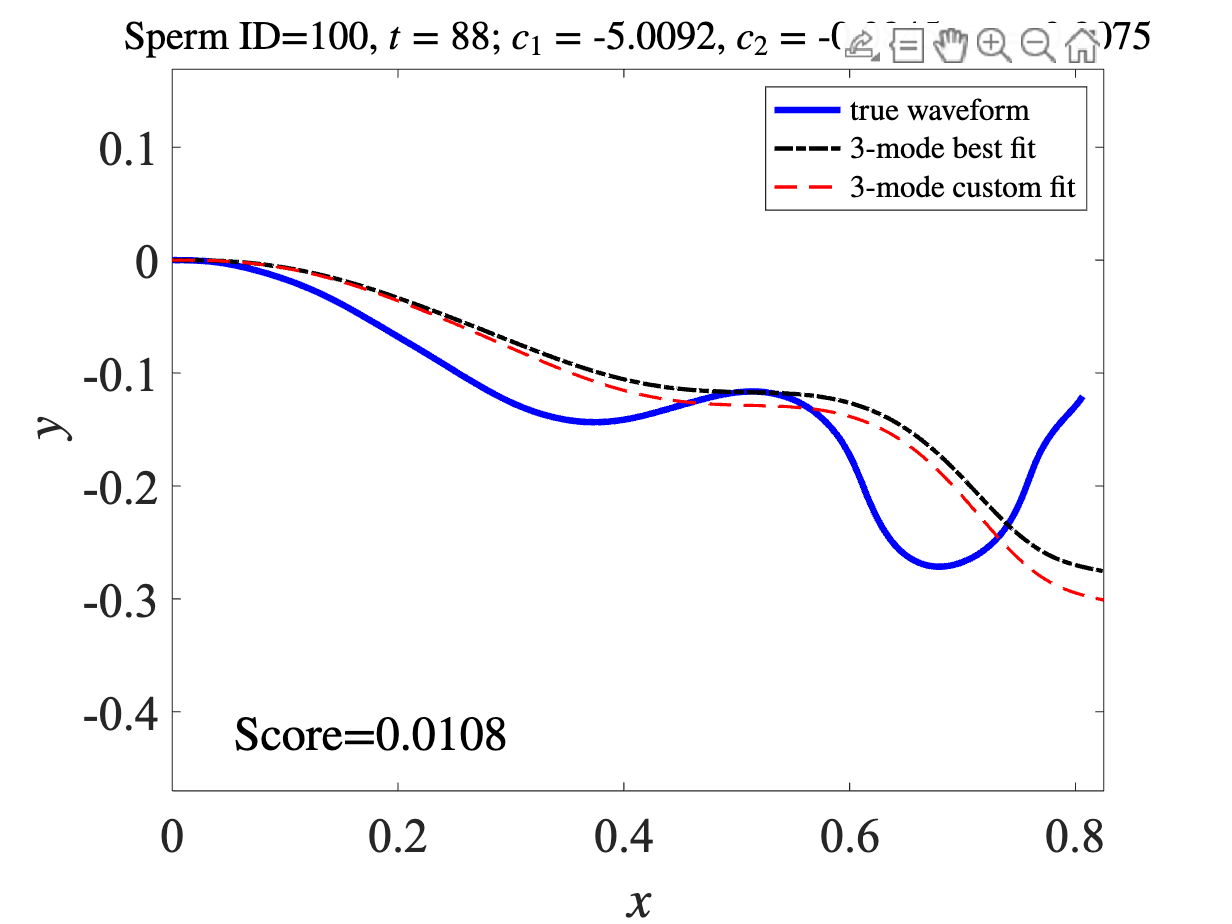

if exist('coeff_op','var') && exist('modes_op','var') && exist('mu_op','var') && exist('sp_num','var')
    clearvars -except coeff_op modes_op mu_op sp_num
else
    clear all
end

if ~exist('coeff_op', 'var')
    load('data_pca_2kModes_vShort.mat', 'coeff_op', 'modes_op', 'mu_op')
    % load_pop_pca_2kModes
    load_all_data     %%% Work in Progress
end

coeff_3 = coeff_op(:,1:3);
modes_3 = modes_op(:,1:3);

% x and y components of first three principal modes
m1x = modes_3(1:1000,1); m1y = modes_3(1001:2000,1);
m2x = modes_3(1:1000,2); m2y = modes_3(1001:2000,2);
m3x = modes_3(1:1000,3); m3y = modes_3(1001:2000,3);

if ~exist('sp_num', 'var')
    sp_num = randi([1 216]); % sperm cell no. whose beating you want to see; can be from 1 to 216
end

tStep  = 88; % time step at which to reconstruct the flagellar waveform

 

% mean x,y position of all the flagellar waveform data (all cells and at
% all times)
mu_x = mu_op(1:1000);
mu_y = mu_op(1001:2000);

% coefficients (at all 100 time-steps) of the first 3 principal modes
c1_mat = reshape(coeff_3(:,1),[100, 216]);
c2_mat = reshape(coeff_3(:,2),[100, 216]);
c3_mat = reshape(coeff_3(:,3),[100, 216]);

% c1, c2 and c3 for sperm ID = sp_num for all 100 time steps (size = 100 x 1)
cs_1 = coeff_3((sp_num - 1) * 100 + 1:(sp_num - 1) * 100 + 100, 1);
cs_2 = coeff_3((sp_num - 1) * 100 + 1:(sp_num - 1) * 100 + 100, 2);
cs_3 = coeff_3((sp_num - 1) * 100 + 1:(sp_num - 1) * 100 + 100, 3);

% best-fit ci's for sperm ID = sp_num for the prescribed time step (the "correct" c)
c1_corr = cs_1(tStep);
c2_corr = cs_2(tStep);
c3_corr = cs_3(tStep);

% row number corresponding to the experimentally obtained waveform
row_act = (sp_num - 1) * 100 + tStep;

% setting up sliders for ci's to be selected by the user (for the custom fit)
c1_r = 0.35 + rand() * 0.30;
c2_r = 0.35 + rand() * 0.30;
c3_r = 0.35 + rand() * 0.30;

% ci_min:  minimum value on the slider for the i-th coefficient
% ci_max:  maximum value on the slider for the i-th coefficient
% ci_def:  default value on the slider for the i-th coefficient
% ci_step: the value of the i-th coefficient can be changed only in step-sizes given by ci_step

c1_min  = min( c1_corr*[ (1 - c1_r) (1 + (1-c1_r)) ] ); 
c1_max  = max( c1_corr*[ (1 - c1_r) (1 + (1-c1_r)) ] );
c1_step = 1/20*( c1_max - c1_min );
c1_def = 1/2*(c1_min + c1_max);

c2_min = min( c2_corr*[ (1 - c2_r) (1 + (1-c2_r)) ] );
c2_max = max( c2_corr*[ (1 - c2_r) (1 + (1-c2_r)) ] );
c2_step = 1/20*( c2_max - c2_min );
c2_def = 1/2*(c2_min + c2_max);

c3_min = min( c3_corr*[ (1 - c3_r) (1 + (1-c3_r)) ] );
c3_max = max( c3_corr*[ (1 - c3_r) (1 + (1-c3_r)) ] );
c3_step = 1/20*( c3_max - c3_min );
c3_def = 1/2*(c3_min + c3_max);

c1_sel = -5.009205746670717;
c2_sel = -0.0845367642806149;
c3_sel =  0.2075034445741875;

% x,y coords. of the true waveform, evaluated by taking 200 modes
xy_act = sum( coeff_op(row_act,1:200) .* modes_op(:,1:200), 2 );

figure
clf
h_act = plot(xy_act(1:1000) + mu_x', xy_act(1001:2000) + mu_y', '-', 'linewidth', 3, 'color', 'b'); hold all

h_corr = plot( ( c1_corr * m1x + c2_corr * m2x + c3_corr * m3x ) + mu_x', ...
    ( c1_corr * m1y + c2_corr * m2y + c3_corr * m3y ) + mu_y', 'color', 'k', 'LineStyle', '-.', 'LineWidth', 2);

h_sel = plot( ( c1_sel * m1x + c2_sel * m2x + c3_sel * m3x ) + mu_x', ...
    ( c1_sel * m1y + c2_sel * m2y + c3_sel * m3y ) + mu_y', 'color', 'r', 'LineStyle', '--', 'LineWidth', 1.5);

%%%% new lines (score calculation): START
x_corr = ( c1_corr * m1x + c2_corr * m2x + c3_corr * m3x ) + mu_x';
x_sel  = ( c1_sel * m1x + c2_sel * m2x + c3_sel * m3x ) + mu_x';
x_act  = xy_act(1:1000) + mu_x';

y_corr = ( c1_corr * m1y + c2_corr * m2y + c3_corr * m3y ) + mu_y';
y_sel  = ( c1_sel * m1y + c2_sel * m2y + c3_sel * m3y ) + mu_y';
y_act  = xy_act(1001:2000) + mu_y';

dist_corr = sum( sqrt( (x_corr - x_act).^2 + (y_corr - y_act).^2 ) );
dist_sel  = sum( sqrt( (x_sel - x_act).^2 + (y_sel - y_act).^2 ) );

% score = dist_sel/dist_corr;
score = sum( sqrt( (x_corr - x_sel).^2 + (y_corr - y_sel).^2 ) )/1000;
%%%% new lines (score calculation): STOP

xlabel( '$x$', 'interpreter', 'latex', 'fontsize', 22 );
ylabel( '$y$', 'interpreter', 'latex', 'fontsize', 22 );
set( gca, 'fontsize', 22, 'fontname', 'times new roman' );

axis equal

title( strcat( 'Sperm ID=', num2str(sp_num), ', $t=$', num2str(tStep),'; $c_1=$', num2str(c1_sel, '%.4f'),', $c_2=$', num2str(c2_sel, '%.4f'),', $c_3=$', num2str(c3_sel, '%.4f') ) , 'interpreter', 'latex', 'fontsize', 18 )
xtxt = gca().XLim(1) + 0.05;
ytxt = gca().YLim(1) + 0.05;

text( xtxt, ytxt, strcat('Score=', num2str(score,'%.4f')), 'interpreter', 'latex','FontSize',22)

legend('true waveform', '3-mode best fit', '3-mode custom fit', 'Location', 'northeast', 'interpreter', 'latex','FontSize',14)

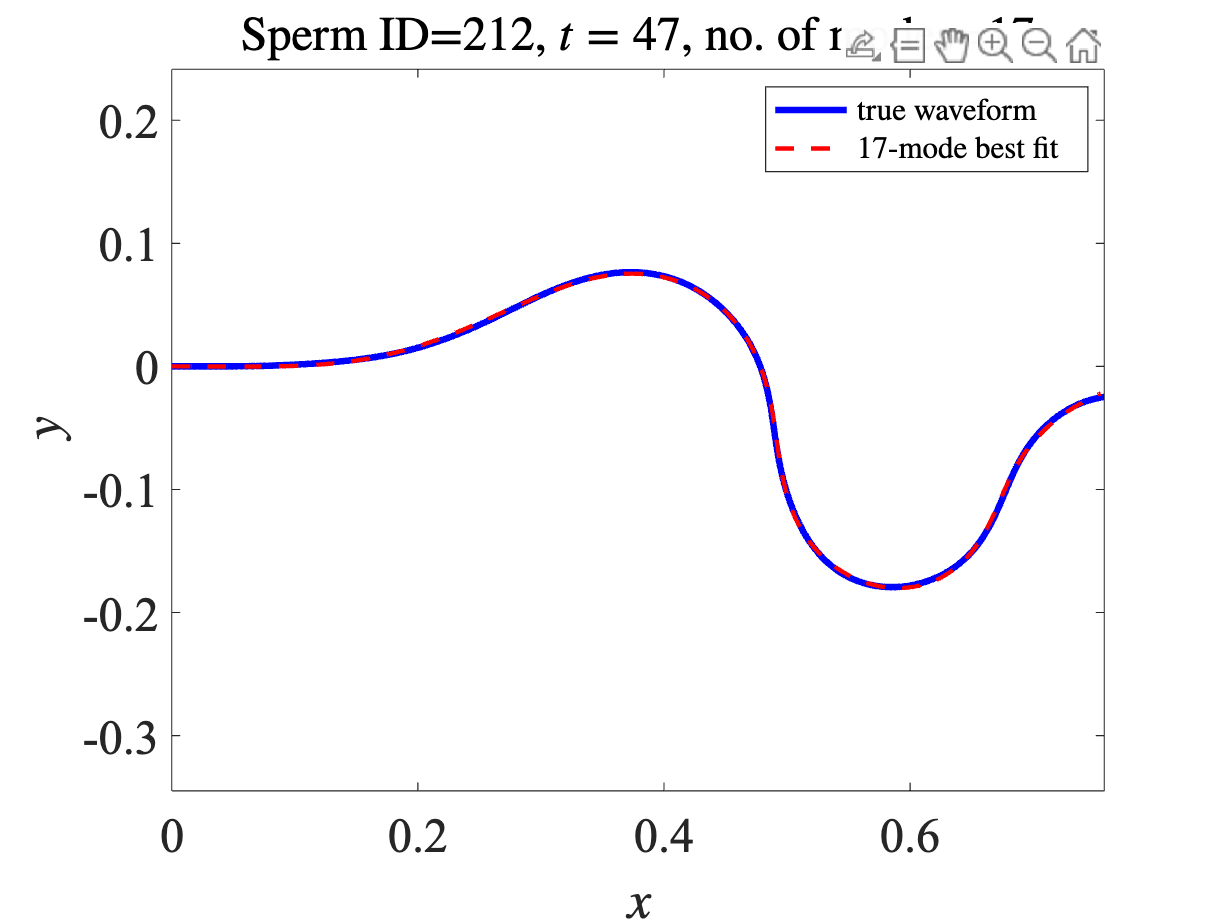

rec_modes = 17;

%%% function which reconstructs the shape of the flagellum, for a
%%% prescribed sperm ID, time-step and number of principal components/modes
recon_func(sp_num, tStep, rec_modes, coeff_op, modes_op, mu_op);